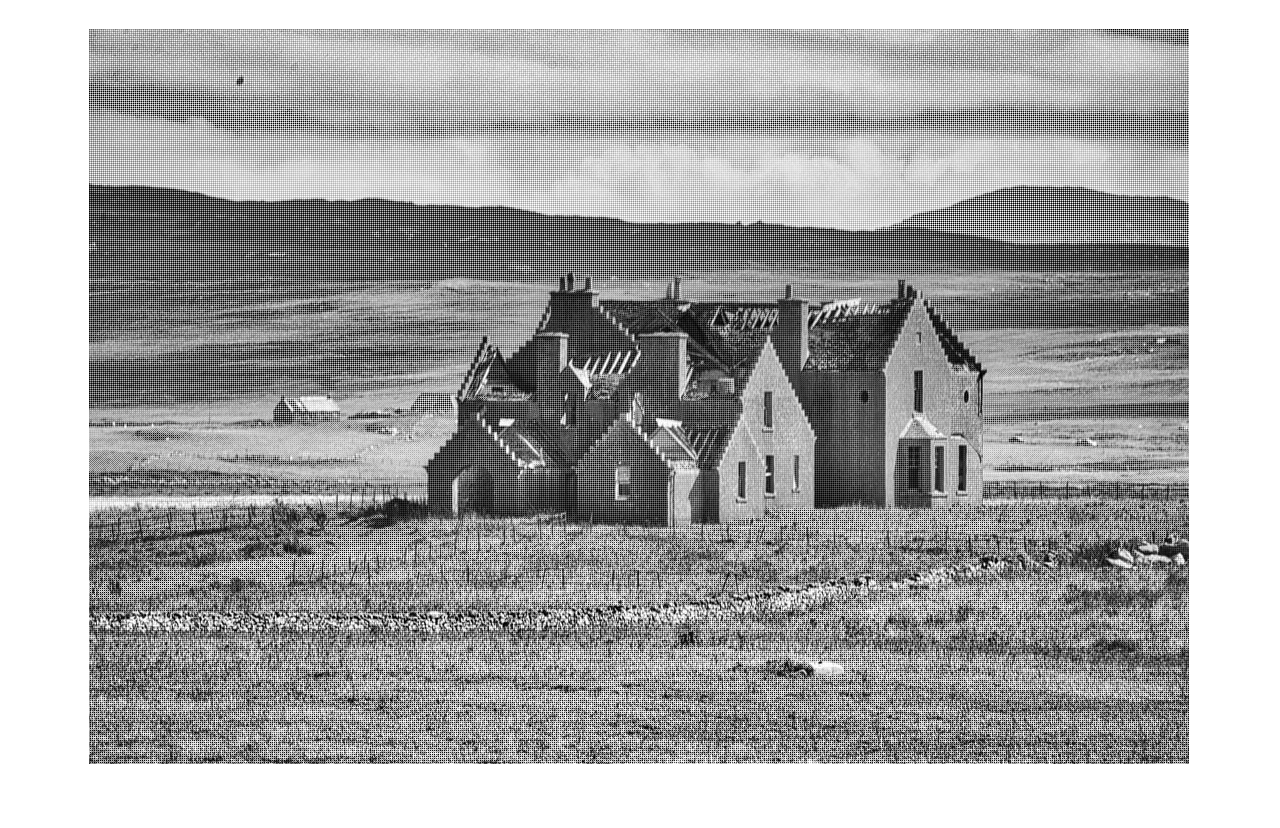

clc;clear all;close all;
I = double(imread('Image3.jpeg'));%error1:not converted to double
[M,N,L] = size(I);

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

J(1:2:M,1:2:N) = R(1:2:M,1:2:N);
J(2:2:M,2:2:N) = B(2:2:M,2:2:N);
J(1:2:M,2:2:N) = G(1:2:M,2:2:N); % error 2:the value of R/B channel may also be 0
J(2:2:M,1:2:N) = G(2:2:M,1:2:N); % error 2:the value of R/B channel may also be 0

figure,imshow(uint8(J),[]);

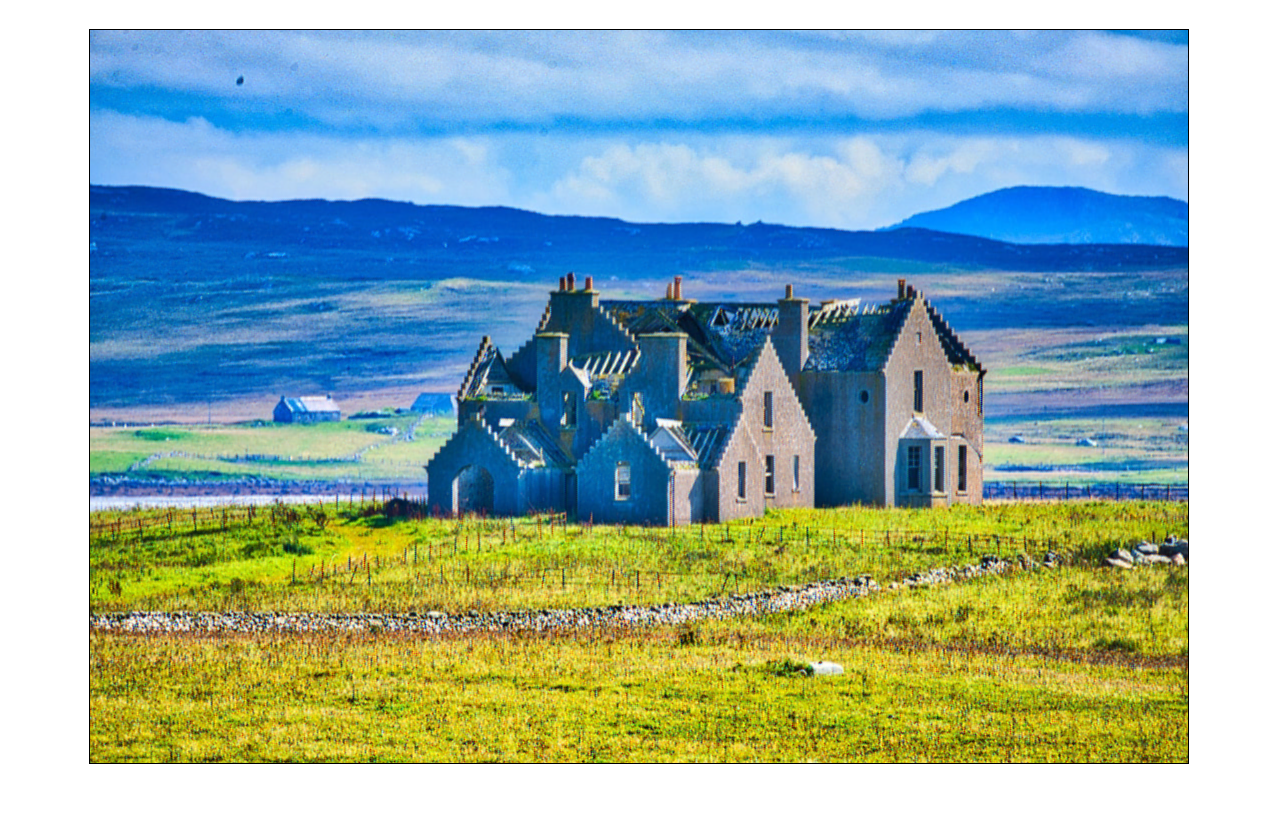




T = zeros(M,N,3);
for i = 2:M-1%%%%%% error3:out of range
    for j = 2:N-1%% error3:out of range
        if mod(i,2) == 0 && mod(j,2) == 1 
            T(i,j,1)=round((J(i-1,j)+J(i+1,j))/2);
            T(i,j,2)=round(J(i,j));
            T(i,j,3)=round((J(i,j-1)+J(i,j+1))/2);
        elseif mod(i,2) == 1 && mod(j,2)==1 % error4:improper'elseif'condition
            T(i,j,1)=round(J(i,j));
            T(i,j,2)=round((J(i-1,j)+J(i+1,j)+J(i,j-1)+J(i,j+1))/4);
            T(i,j,3)=round((J(i-1,j-1)+J(i+1,j+1)+J(i+1,j-1)+J(i-1,j+1))/4);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% error5:typo?'-'shoule be'+'
        elseif mod(i,2) == 1 && mod(j,2) == 0 % error4:improper'elseif'condition
            T(i,j,1)=round((J(i,j-1)+J(i,j+1))/2);
            T(i,j,2)=round(J(i,j));
            T(i,j,3)=round((J(i-1,j)+J(i+1,j))/2);   
        else 
            T(i,j,1)=round((J(i-1,j-1)+J(i+1,j+1)+J(i+1,j-1)+J(i-1,j+1))/4);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% error5:typo?'-'shoule be'+'
            T(i,j,2)=round((J(i-1,j)+J(i+1,j)+J(i,j-1)+J(i,j+1))/4);
            T(i,j,3)=round(J(i,j));
        end
    end
end
figure,imshow(uint8(T),[]);